# Sensitivity analysis (fluorescence excitation spectra)

% Author: Abbas El Moussawi
% COPYRIGHT 2024: EMPI-RF - University of Duisburg-Essen  
init;

## **Species**

species = availableSpecies(1);


*    Add new species in .mat format under ".\LIFSim4.0\input-data\lines\" , *

*    see documentation section "Importing lines and partition function" for details*

## **Laser parameters**

unit = '1/cm';
defStep = 0.05;
if strcmpi(unit,'nm')
    defStep = 0.0001;
end

%224.97 - 225.22 ~ 44400 - 44450
startwn = 44300 ;
checkWnum(unit,startwn);
endwn = 44500;
checkWnum(unit,endwn);
step = 0.066;
dnuGL = 0.18;
dnuLL = 0.01;

excWnum = startwn:step:endwn;

plotWnum = excWnum;
if strcmpi(unit,'nm')
    excWnum = convWnumWlen(excWnum);
    dnuGL = convWnumWlen(dnuGL,endwn);
    dnuLL = convWnumWlen(dnuLL, endwn);
end
 
[linelist, Z, n, ~,MM, emList, listAsCell] = selectLines(species,excWnum);

linepos = cell2mat(listAsCell(:,4));

if n == 0
    warning("No lines found.")
    return;
end


## Synthesis parameters

### Spectral region of interests (sROIs)

sROISize = 10;

sROI_auto  = 1;
switch sROI_auto
    case 1
        sROIs = startwn:sROISize:endwn;
    case 2
        movingWindow =  1;
        sROIs = startwn:movingWindow:endwn;
    case 3
        sROIs = [44350 44402 44407 44417];
        checkWnum(unit,sROIs(1));
end

extra_sROIs = [];

if ~isempty(extra_sROIs)
    sROIs = sort(unique([extra_sROIs, sROIs]));

end
if sROIs(end)== endwn, sROIs(end) = []; end


### **Numerical measurement**

repetitions = 10;
SNR = 15; % in dB



## Environment

### Temperature range


Tmin = 1500;
Tmax = 2500;
TCounts = 10;
TRange = linspace(Tmin, Tmax, TCounts);
TRange = ceil(TRange/10)*10;
disp(['Target temperature(s) ' num2str(TRange) ' K'])

Target temperature(s) 1500  1620  1730  1840  1950  2060  2170  2280  2390  2500 K



varargin = {  "Z", Z};


### Pressure and collisions data

P = 0.1;

colls =  collisions(species);
gas = table(0,0);

if ~isempty(colls)
    path = "D:\Cloud\OneDrive - Universitaet Duisburg-Essen\06_dev\git\LIFSim4.0\input-data\gas-compositions\air+NO.csv";

*   (Support for NO, otherwise update function 'collissions')*

    gas = loadGasComposition(path);
end


[specs, noisy] = generateTRange(TRange, excWnum, linelist, MM, P=P, ...
    dnuGL=dnuGL, dnuLL=dnuLL, snr=SNR, repetitions=repetitions, ...
    colls=colls, gas= gas, Z=Z);

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 6 workers.


### Preview synthetic spectrum

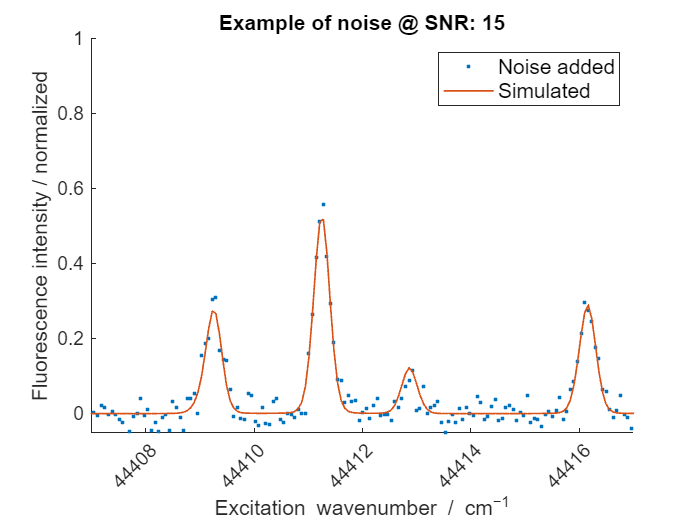

exampleROI = 44407;
 

if exampleROI < startwn

    exampleROI = startwn;
elseif exampleROI >= endwn-sROISize
    exampleROI = exampleROI-sROISize;
end

figure, hold on,

plot(excWnum, noisy{end}.spec(1,:), DisplayName='Noise added', Marker='.', MarkerSize=6, LineStyle='none')
plot(excWnum, specs(end,:), DisplayName='Simulated', LineWidth=1)
legend show
ytickformat("auto");
ylabel('LIF intensity / arb.u.')
xlim([exampleROI exampleROI+sROISize])
ylim([-0.05 1])
title(['Example of noise @ SNR: ' num2str(SNR)])
LABELS("flourIntNorm");
LABELS("1/cm");

drawnow;


### Results plot

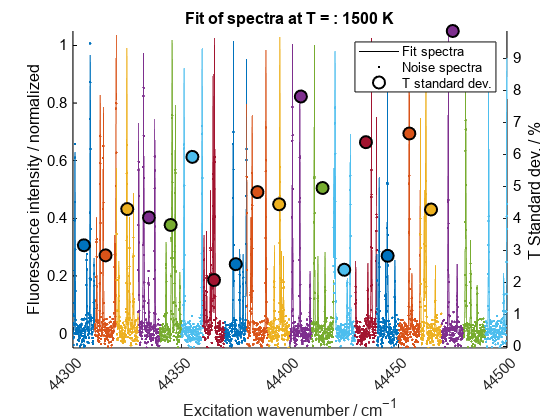

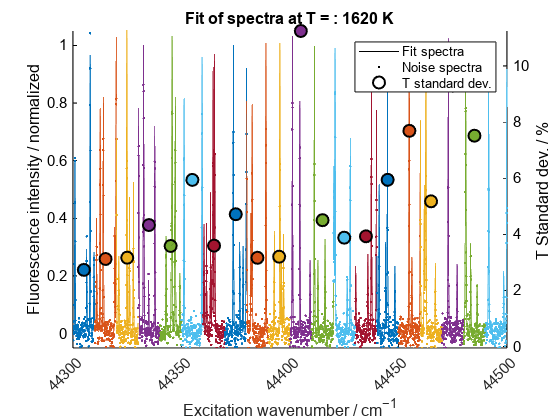

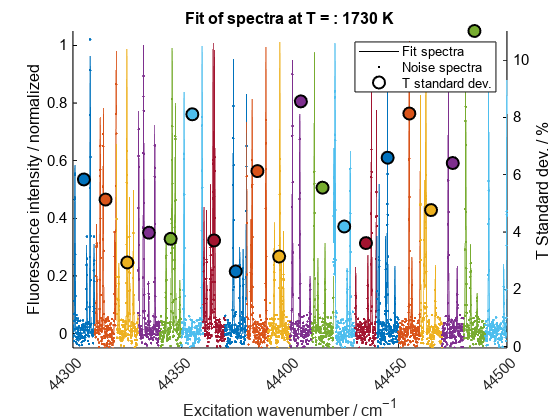

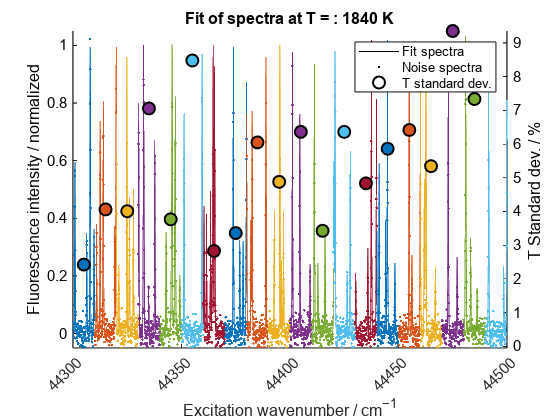

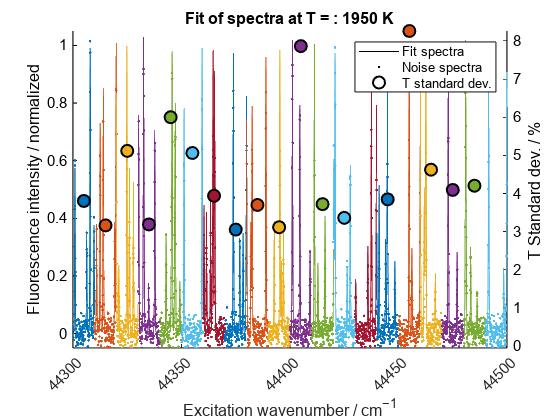

 

num_timesteps = numel(sROIs);
colors = lines(num_timesteps);

clear num_timesteps

laser = 2*(dnuGL+dnuLL);


LW=1.5;
MS = 9;

ROIStdRange = zeros(TCounts,length(sROIs));
ROITMeanRange = zeros(TCounts,length(sROIs));
ROIResidMean = zeros(TCounts,length(sROIs));
figures = cell(TCounts,1);
tic
for t = 1:TCounts
    %disp(['Fitting spectra at T = ' num2str(TRange(t)) ' K'])
    TFit = NaN(repetitions, length(sROIs));
    Resid = zeros(repetitions, length(sROIs));
    noisy{t}.cMid = zeros(1, length(sROIs));


    figures{t} = figure;
    hold on;
    title(['Fit of spectra at T = : ' num2str(TRange(t)) ' K'])
    LABELS("1/cm");
    yyaxis right
    set(gca,YColor='black');
    ylabel 'T Standard dev. / % '


    yyaxis left
    % ylabel('LIF intensity / arb.u.', Color='black')
    LABELS("flourIntNorm");
    set(gca,YColor='black');

    plot(excWnum(1:2), [-1 -1], Color='black', Marker="none", LineStyle="-")
    plot(excWnum(1:2), [-1 -1], Color='black', Marker=".", LineStyle="none")
    plot(excWnum(1:2), [-1 -1], Color='black', Marker="o", LineStyle="none", LineWidth=LW, MarkerSize=MS)

    ylim([-0.05 1.05])

    i = 0;
    for c = sROIs
        i = i +1;
        cStart = c;
        cEnd = c+sROISize;

        if cEnd>endwn, cEnd=endwn; end

        fc = find(excWnum>=cStart & excWnum<=cEnd);
        if isempty(fc)
            % i = i +1;
            continue; % to do
        end

        cExcWnum = excWnum(fc);
        f = find(linepos>=(cExcWnum(1)-laser) & linepos<=(cExcWnum(end)+laser));

        if isempty(f)
            continue;  % to do
        end
        noisy{t}.cMid(i) = c+sROISize/2;

        L = linelist(f);

        bestGuess = [noisy{t}.T+rand(1,1)*300, dnuGL, dnuLL, 1, 0, 0, 0];
        options = getFitOptions(id='lsqnonlin');
        options.Display="none";


        images3d = reshape(noisy{t}.spec(:, fc), [1, repetitions, length(cExcWnum)]);

        [fittedImage, fitResidue] = fitExcImageDataset(cExcWnum, images3d,...
            MM, L, [1 1], bestGuess, true(1,repetitions),options, ...
            false, Z=Z);


        for r = 1:repetitions
            noisySpec = noisy{t}.spec(r, fc);
            Resid(r, i) = fitResidue(r);
            TFit(r, i) = fittedImage(1,r,1);
        end

        plotColor = colors(i, :);

        sss = excitationSpecSolution(cExcWnum, L, MM,fittedImage(1,r,:), varargin{:});

        plot(cExcWnum, noisySpec , Color=plotColor, Marker=".", LineStyle="none", LineWidth=2)
        noisy{t}.fits{i} = sss;%.*max(noisySpec);
        plot(cExcWnum, noisy{t}.fits{i}, Color=plotColor, Marker="none", LineStyle="-")


        noisy{t}.cExcWnum{i} = cExcWnum;

    end

    noisy{t}.TFit = TFit;
    noisy{t}.TStd = std(TFit,0,1);
    noisy{t}.TStdPerc = 100*std(TFit,0,1)./TRange(t);



    noisy{t}.TMean = mean(TFit,1);
    noisy{t}.Resid = Resid;


    ROIStdRange(t,:) = noisy{t}.TStdPerc;
    ROITMeanRange(t,:) = noisy{t}.TMean;


    yyaxis right
    for j = 1:i-1
        plotColor = colors(j, :);
        if (noisy{t}.TStdPerc(j) == 0)
            continue;
        end
        plot(noisy{t}.cMid(j), noisy{t}.TStdPerc(j), Marker='o', MarkerSize=MS, LineStyle='none', MarkerEdgeColor='black', MarkerFaceColor=plotColor, LineWidth=LW)
    end
    ylim([-0.05 max(noisy{t}.TStdPerc)])
    legend('Fit spectra','Noise spectra', 'T standard dev.');
    drawnow;
end

toc



clear sss i plotColor TFit noisySpec Resid


### Results analysis

legendShow =  true;

f1 = figure;
hold on


plot(TRange,TRange, '-', DisplayName='Real temperature', Color='black')
legend show
xlabel('Given temperature / K')

f2 = figure;
% set(f2,'Visible','off');
hold on

if legendShow
    figure(f1)
    legend show
    legend("Position", [0.6967 0.2926 0.2571, 0.3190])
    figure(f2)
    legend(Position=    [0.6770 0.1332 0.2179, 0.1810])
    legend show
else
    figure(f1)
    legend hide
    figure(f2)
    legend hide
end

xlabel('Given temperature / K')
meanStds = zeros(sROISize,1);
for i = 1:length(sROIs)
    r = ROIStdRange(:,i);

    meanStds(i) = mean(r);

    if meanStds(i)>4|| isnan(mean(r))

        continue;
    end

 

    sROIstart = round(sROIs(i),2);
    sROIend = sROISize +sROIstart;

    uu = 'cm^{-1}';

    if strcmpi(unit,'nm')
        sROIstart = convWnumWlen(sROIstart);
        sROIend = convWnumWlen(sROIend);

        uu = 'nm';
        sROIstart = round(sROIstart,4);
        sROIend = round(sROIend,4);
    end

    dispname = ['i: ' num2str(i) ', '  num2str(sROIstart) '-' num2str(sROIend) ' '  uu ];

    plotColor = colors(i, :);

    figure(f1)
    plot(TRange,ROITMeanRange(:,i), 'o', DisplayName=dispname, Color=plotColor)


    ylabel 'Mean fit temperature / K '

    figure(f2)
    ylabel 'T Standard dev. / % '
    plot(TRange,r, Marker='o',LineStyle='-', DisplayName=dispname, Color=plotColor)
end


return
% print -dsvg  ddd.svg

 
close all

x = ['livescripts\sensitivityWorkspace\' getTimeStamp '_5cm.mat'];
save(x);